Here we define the objects in the physical boat system including the boat, mast, and ballast.

boat.L = 0.5; % length in meters
boat.HL = boat.L /2

boat = struct with fields:
     L: 0.5000
    HL: 0.2500


boat.W = 0.24; % width in meters
boat.HB = boat.W / 2; % half breadth in meters
boat.D = 0.14; % depth in meters
boat.mass = 0.2177243 % mass of boat in kg

boat = struct with fields:
       L: 0.5000
      HL: 0.2500
       W: 0.2400
      HB: 0.1200
       D: 0.1400
    mass: 0.2177



%boat.material_density = 2.821; % kg/m^3
boat.theta = 0; % heel angle in degrees

mast.mass = 0.096; % kg
mast.length_under_deck = 0.12;
mast.COMz = boat.D + (0.25 - mast.length_under_deck);

ballast.mass = 1; % kg
ballast.z_from_ground = 0.02

ballast = struct with fields:
             mass: 1
    z_from_ground: 0.0200



dx = 0.001; % cell step_x in meters
dy = 0.001; % cell step_y in meters
dz = 0.001; % cell step_z in meters

mesh.xs = -boat.HL:dx:boat.HL

mesh = struct with fields:
    xs: [1×501 double]


mesh.ys = -boat.HB:dy:boat.HB;
mesh.zs = 0:dz:boat.D;

[mesh.xgrid,mesh.ygrid,mesh.zgrid] = meshgrid(mesh.xs,mesh.ys,mesh.zs);

Here we define the actual hull in the meshgrid and calculate its COM. Currently, the COM is hardcoded to the one calculated in the Solidworks model of our boat.

boat.hull = computeHull(mesh,boat)

boat = struct with fields:
        L: 0.5000
       HL: 0.2500
        W: 0.2400
       HB: 0.1200
        D: 0.1400
     mass: 0.2177
    theta: 0
     hull: [241×501×141 logical]



mesh.dV = dx * dy * dz % cell volume in m^3

mesh = struct with fields:
       xs: [1×501 double]
       ys: [1×241 double]
       zs: [1×141 double]
    xgrid: [241×501×141 double]
    ygrid: [241×501×141 double]
    zgrid: [241×501×141 double]
       dV: 1.0000e-09


total_cells = sum(sum(sum(boat.hull)))

total_cells = 7447056

boat.volume = total_cells * mesh.dV

boat = struct with fields:
         L: 0.5000
        HL: 0.2500
         W: 0.2400
        HB: 0.1200
         D: 0.1400
      mass: 0.2177
     theta: 0
      hull: [241×501×141 logical]
    volume: 0.0074



boat.density = boat.mass / boat.volume % in kg/m^3

boat = struct with fields:
          L: 0.5000
         HL: 0.2500
          W: 0.2400
         HB: 0.1200
          D: 0.1400
       mass: 0.2177
      theta: 0
       hull: [241×501×141 logical]
     volume: 0.0074
    density: 29.2363


mass_per_cell = mesh.dV * boat.density; % in kg/m^3

masses = boat.hull * mass_per_cell

masses = 
(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

M = sum(masses(:))

M = 0.2177


COM = centerOfMass3_boat(masses,mesh,mast,ballast,boat)

COM =    -0.0000    0.0000    0.0491


COM = [0,0,0.0464]

COM =          0         0    0.0464


Here, we run a for loop to calculate the moment at an array of theta values in order to generate an AVS curve for the boat.

thetas = [0, 10, 20, 40, 60, 80, 100, 120, 130,140, 160, 180]

thetas =      0    10    20    40    60    80   100   120   130   140   160   180


moment = [];

for theta = thetas
    boat.theta = theta
    fun = @(d) (findMassDiff(d,boat,mesh,mast,ballast));
    depth = fzero(fun,boat.D / 2)
    
    water = computeWater(depth,boat.theta,mesh);
    
    sub_region = boat.hull & water;
    
    
    COB = centerOfMass3(sub_region,mesh) % COB of sub_region
    
    R = COB - COM
    
    Fb = (boat.mass + mast.mass + ballast.mass) * 9.81;
    
    Fbj = cosd(boat.theta + 90)
    Fbk = sind(boat.theta + 90)
    
    FbV = Fb * [0,Fbj,Fbk];
    
    T = cross(R,FbV)
    moment = [moment,T(1)];
end

boat = struct with fields:
          L: 0.5000
         HL: 0.2500
          W: 0.2400
         HB: 0.1200
          D: 0.1400
       mass: 0.2177
      theta: 0
       hull: [241×501×141 logical]
     volume: 0.0074
    density: 29.2363


depth = 0.0460

COB =    -0.0000   -0.0000    0.0289


R =    -0.0000   -0.0000   -0.0175


Fbj = 0

Fbk = 1

T =    1.0e-16 *

   -0.3458    0.0564         0


boat = struct with fields:
          L: 0.5000
         HL: 0.2500
          W: 0.2400
         HB: 0.1200
          D: 0.1400
       mass: 0.2177
      theta: 10
       hull: [241×501×141 logical]
     volume: 0.0074
    density: 29.2363


depth = 0.0452

COB =    -0.0000    0.0282    0.0311


R =    -0.0000    0.0282   -0.0153


Fbj = -0.1736

Fbk = 0.9848

T =     0.3233    0.0000    0.0000


boat = struct with fields:
          L: 0.5000
         HL: 0.2500
          W: 0.2400
         HB: 0.1200
          D: 0.1400
       mass: 0.2177
      theta: 20
       hull: [241×501×141 logical]
     volume: 0.0074
    density: 29.2363


depth = 0.0415

COB =    -0.0000    0.0529    0.0377


R =    -0.0000    0.0529   -0.0087


Fbj = -0.3420

Fbk = 0.9397

T =     0.6028    0.0000    0.0000


boat = struct with fields:
          L: 0.5000
         HL: 0.2500
          W: 0.2400
         HB: 0.1200
          D: 0.1400
       mass: 0.2177
      theta: 40
       hull: [241×501×141 logical]
     volume: 0.0074
    density: 29.2363


depth = 0.0178

COB =     0.0000    0.0791    0.0522


R =     0.0000    0.0791    0.0058


Fbj = -0.6428

Fbk = 0.7660

T =     0.8288   -0.0000   -0.0000


boat = struct with fields:
          L: 0.5000
         HL: 0.2500
          W: 0.2400
         HB: 0.1200
          D: 0.1400
       mass: 0.2177
      theta: 60
       hull: [241×501×141 logical]
     volume: 0.0074
    density: 29.2363


depth = -0.0477

COB =     0.0000    0.0931    0.0686


R =     0.0000    0.0931    0.0222


Fbj = -0.8660

Fbk = 0.5000

T =     0.8475   -0.0000   -0.0000


boat = struct with fields:
          L: 0.5000
         HL: 0.2500
          W: 0.2400
         HB: 0.1200
          D: 0.1400
       mass: 0.2177
      theta: 80
       hull: [241×501×141 logical]
     volume: 0.0074
    density: 29.2363


depth = -0.3487

COB =    -0.0000    0.0978    0.0812


R =    -0.0000    0.0978    0.0348


Fbj = -0.9848

Fbk = 0.1736

T =     0.6608    0.0000    0.0000


boat = struct with fields:
          L: 0.5000
         HL: 0.2500
          W: 0.2400
         HB: 0.1200
          D: 0.1400
       mass: 0.2177
      theta: 100
       hull: [241×501×141 logical]
     volume: 0.0074
    density: 29.2363


depth = 0.5200

COB =     0.0000    0.0979    0.0918


R =     0.0000    0.0979    0.0454


Fbj = -0.9848

Fbk = -0.1736

T =     0.3576    0.0000   -0.0000


boat = struct with fields:
          L: 0.5000
         HL: 0.2500
          W: 0.2400
         HB: 0.1200
          D: 0.1400
       mass: 0.2177
      theta: 120
       hull: [241×501×141 logical]
     volume: 0.0074
    density: 29.2363


depth = 0.2192

COB =     0.0000    0.0936    0.1032


R =     0.0000    0.0936    0.0568


Fbj = -0.8660

Fbk = -0.5000

T =     0.0304    0.0000   -0.0000


boat = struct with fields:
          L: 0.5000
         HL: 0.2500
          W: 0.2400
         HB: 0.1200
          D: 0.1400
       mass: 0.2177
      theta: 130
       hull: [241×501×141 logical]
     volume: 0.0074
    density: 29.2363


depth = 0.1792

COB =    -0.0000    0.0896    0.1090


R =    -0.0000    0.0896    0.0626


Fbj = -0.7660

Fbk = -0.6428

T =    -0.1244   -0.0000    0.0000


boat = struct with fields:
          L: 0.5000
         HL: 0.2500
          W: 0.2400
         HB: 0.1200
          D: 0.1400
       mass: 0.2177
      theta: 140
       hull: [241×501×141 logical]
     volume: 0.0074
    density: 29.2363


depth = 0.1552

COB =    -0.0000    0.0847    0.1138


R =    -0.0000    0.0847    0.0674


Fbj = -0.6428

Fbk = -0.7660

T =    -0.2775   -0.0000    0.0000


boat = struct with fields:
          L: 0.5000
         HL: 0.2500
          W: 0.2400
         HB: 0.1200
          D: 0.1400
       mass: 0.2177
      theta: 160
       hull: [241×501×141 logical]
     volume: 0.0074
    density: 29.2363


depth = 0.1289

COB =    -0.0000    0.0684    0.1228


R =    -0.0000    0.0684    0.0764


Fbj = -0.3420

Fbk = -0.9397

T =    -0.4912   -0.0000    0.0000


boat = struct with fields:
          L: 0.5000
         HL: 0.2500
          W: 0.2400
         HB: 0.1200
          D: 0.1400
       mass: 0.2177
      theta: 180
       hull: [241×501×141 logical]
     volume: 0.0074
    density: 29.2363


depth = 0.1240

COB =     0.0000   -0.0000    0.1321


R =     0.0000   -0.0000    0.0857


Fbj = 0

Fbk = -1

T =    1.0e-16 *

    0.4074    0.1315         0


Below, we interpolate the AVS curve in order to make it appear smoother.

%plot(thetas,moment,'bo')
xq = 0:5:180;
vq = interp1(thetas,moment,xq,'spline');

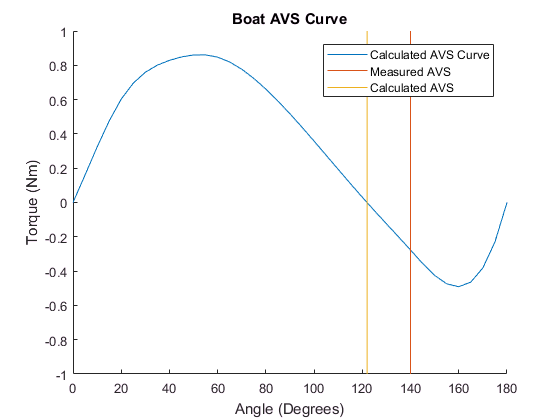

clf
hold on 
plot(xq,vq)
plot([140,140],[-1,1])
plot([122,122],[-1,1])
legend('Calculated AVS Curve','Measured AVS','Calculated AVS')
hold off
title('Boat AVS Curve')
xlabel('Angle (Degrees)')
ylabel('Torque (Nm)')

Creates a surface plot of the inputted hull shape.

ans =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.1396    0.1385    0.1376    0.1368    0.1361    0.1356    0.1351    0.1348    0.1345   

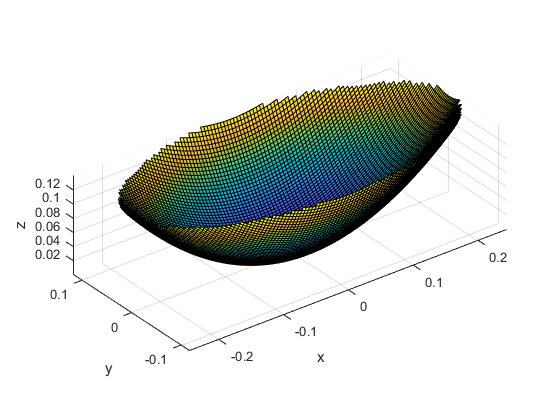

x3d = linspace(-0.25,.25,100);
y3d = linspace(-.12,.12,100);
plotHull(x3d,y3d,boat.D,boat.L,boat.W)

% FUNCTION DEFINITONS

function hull = computeHull(mesh,boat)
    % computeHull: compute the shape of the hull
    % mesh: structure that contains y
    % boat: structure that contains n
    % returns: logical matrix (1 = hull, 0 = not hull)
    
    x = mesh.xgrid;
    y = mesh.ygrid;
    z = (-1*sqrt(boat.D^2.*(1-(4.*y.^2/boat.L^2)))+boat.D+(boat.D/(boat.W/2).^2).*x.^2)/2;
    hull = mesh.zgrid > z;
end

function water = computeWater(d,theta,mesh)
    y = mesh.ygrid;
    
    z = tand(theta) * y + d;
    
    if (theta <= 90 || theta >= 270)
        water = mesh.zgrid < z;
    else
        water = mesh.zgrid > z;
    end
end

function vis_3d_matrix(data)
    h = vol3d('cdata',data==0,'texture','2D');
    newplot;
    view(3);
    vol3d(h);
    alphamap('rampdown'), alphamap('decrease'), alphamap('decrease');
    axis equal
end
    
function plotMatrix(A,mesh,cmap)
    % plotMatrix: plots a matrix using image
    % A: matrix
    % mesh: srtruct containing ys and zs
    % cmap: Colormap
    colormap(cmap);
    image(mesh.zs,mesh.ys,squeeze(A),'AlphaData',0.5);
end

function COM = centerOfMass3(masses,mesh)
    % centerOfMass2: computes center of mass in 2D
    % masses: matrix of masses
    % mesh: structure containing ygrid and zgrid
    % returns: Vector [ycom,zcom]
    M = sum(masses(:));
    
    xcom = sum((sum(sum(masses .* mesh.xgrid)))) / M;
    ycom = sum((sum(sum(masses .* mesh.ygrid)))) / M;
    zcom = sum((sum(sum(masses .* mesh.zgrid)))) / M; 
 
    COM = [xcom,ycom,zcom];
end

function COM = centerOfMass3_boat(masses,mesh,mast,ballast,boat)
    % centerOfMass2: computes center of mass in 2D
    % masses: matrix of masses
    % mesh: structure containing ygrid and zgrid
    % returns: Vector [ycom,zcom]
    M = sum(masses(:));
    
    xcom = sum((sum(sum(masses .* mesh.xgrid)))) / M;
    ycom = sum((sum(sum(masses .* mesh.ygrid)))) / M;
    zcom = sum((sum(sum(masses .* mesh.zgrid)))) / M; 
    
    zcom_final = ((boat.mass * zcom) + (mast.mass * mast.COMz) + (ballast.mass * ballast.z_from_ground)) / (boat.mass + mast.mass + ballast.mass);
    
    COM = [xcom,ycom,zcom_final];
end


function diff = findMassDiff(d,boat,mesh,mast,ballast)
    water = computeWater(d,boat.theta,mesh);
    
    sub_region = boat.hull & water;
    num_cells = sum(sum(sum(sub_region)));
    sub_volume = num_cells * mesh.dV;
    massW = sub_volume * 1000;
    
    diff = massW - (boat.mass + mast.mass + ballast.mass);
end

function res = plotHull(x,y,D,L,B)
    [X,Y] = meshgrid(x,y);
    res = ((D/(B/2).^2).*Y.^2) + ((D/(L/2).^2).*X.^2);
    indicies = find(res > D);
    res(indicies) = NaN;
    surf(X,Y,res)
    colormap default
    xlabel('x')
    ylabel('y')
    zlabel('z')
    shading('faceted')
    axis('equal')
end